# **Matlab案例代码解析**

## 2. 典型绘图案例

### 2.6 特殊绘图

#### 2.6.15 由一系列圆构成的圆环

颜值即正义；

**颜色模板参考：**[**60套优雅的颜色模板**](https://zhuanlan.zhihu.com/p/444970597)

要点：利用极坐标方式绘图

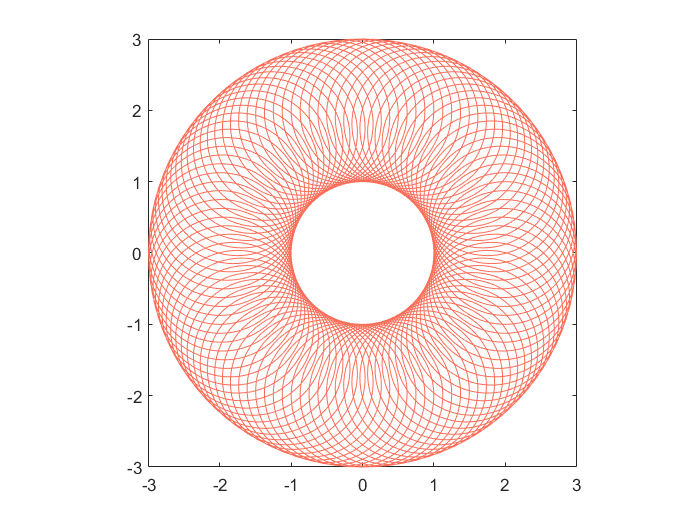

clear;clc;close all;
% 获取到颜色
[all_themes, all_colors] = GetColors(); 
x0 = 0;
y0 = 0;
r1 = 2;
r2 = 1;
theta = 0:pi/50:2*pi;
for i = 1:length(theta)
    % 系列小圆的圆心坐标 极坐标方式
    x = x0 + r1 * cos(theta(i));
    y = y0 + r1 * sin(theta(i));
    % 以小圆圆心画圆 极坐标方式
    xx = x + r2 * cos(theta);
    yy = y + r2 * sin(theta);
    plot(xx, yy, 'Color', all_colors(1, :));
    hold on
end
hold off
% 限定显示范围
xlim([-3, 3]);
ylim([-3, 3]);
% x y 轴等宽
axis equal
% 紧凑
axis tight